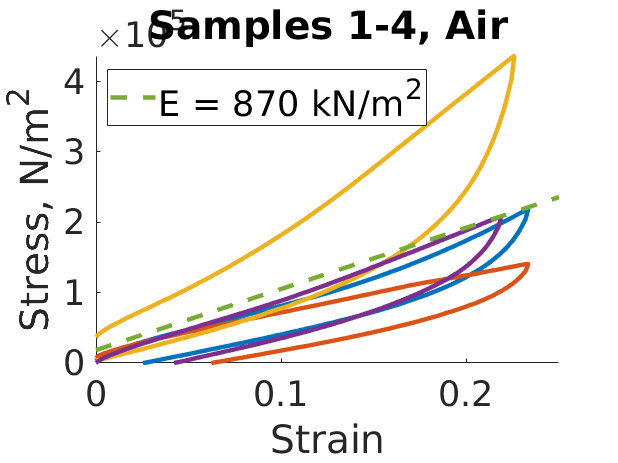

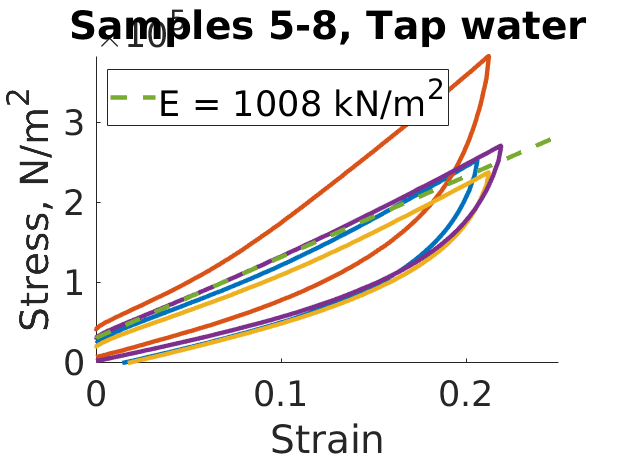

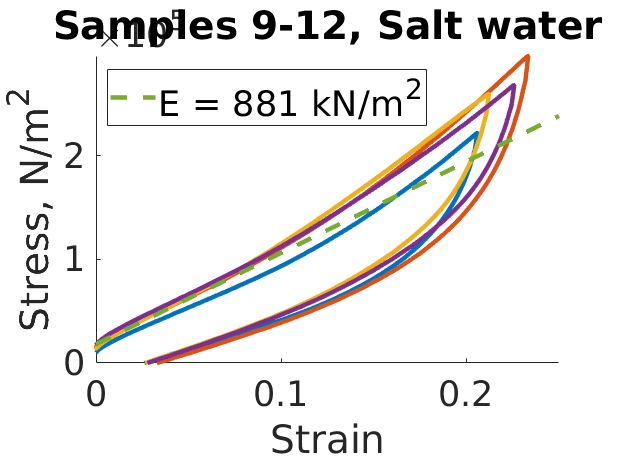

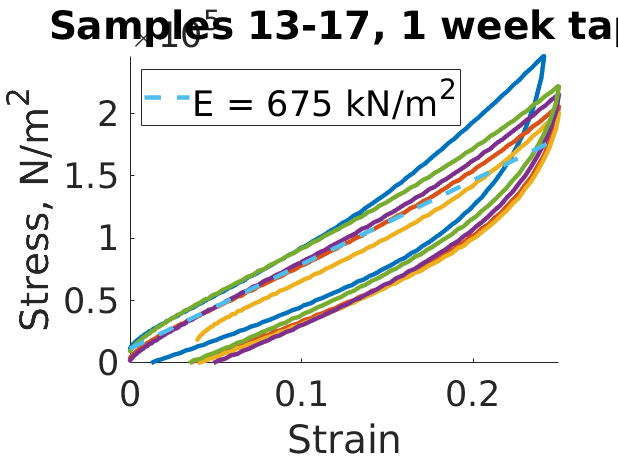

youngsModuli = 	1.0e+06 *

    0.8700
    1.0085
    0.8807
    0.6754
    0.6474


%% Load parameters

allParameters = readmatrix(uigetfile('*.xlsx'));
%%
[filename, filepath] = uigetfile('*.csv');
settings = {allParameters filename filepath};
youngsModuli = [
    generateGraphs(1:4, 'Samples 1-4, Air', settings)
    generateGraphs(5:8, 'Samples 5-8, Tap water', settings)
    generateGraphs(9:12, 'Samples 9-12, Salt water', settings)
    generateGraphs(13:17, 'Samples 13-17, 1 week tap', settings)
    generateGraphs(18:21, 'Samples 13-17, 1 week salt', settings)
]

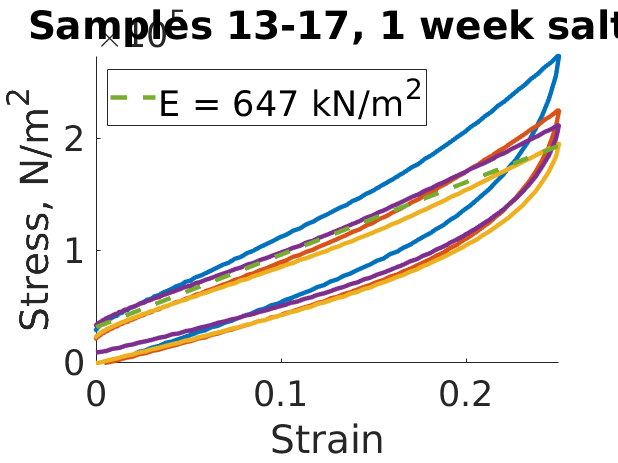

hold off

figure; set(gca, 'FontSize', 24); hold on;
bar([1:5],youngsModuli);
xticks([1:5]);
labels = {'Air', 'Tap water', 'Salt water', '1 week Tap', '1 week Salt'}

labels = 1×5 cell array
    {'Air'}    {'Tap water'}    {'Salt water'}    {'1 week Tap'}    {'1 week Salt'}


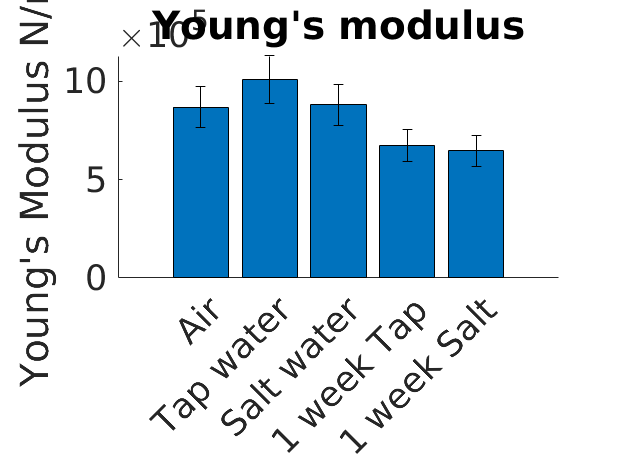

er = errorbar([1:5], youngsModuli, youngsModuli.*0.12, 'LineStyle', "none", "Color","black");
xticklabels(labels); xtickangle(45);
title("Young's modulus"); ylabel("Young's Modulus N/m^2")
hold off

function [stress, strain, time] = process(allParameters, i, filename, filepath)
    for j=1:1
        %Match pattern to dynamically read the files
        filename = regexprep(filename, '_\d+\d?+_+\d', ['_',num2str(i),'_',num2str(j)]);
        T = readmatrix([filepath filename]);
        time = T(:,1);
        displacement = T(:,2).*1e-3; %convert to m
        force=T(:,3);
        %plotTitle=['Sample ' num2str(i)];
        %% Process Data
        % set parameters for the particular graph we're working on.
        parameters=allParameters(allParameters(:,3)==i,:);
        %Take dimensions from our set of parameters
        A=parameters(6)*parameters(4)*1e-6;
        L = parameters(8)*1e-3;
        stress=force/A;
        strain=displacement/L;
    end
end

function makePlot(x, y, makeTitle)
    plot(x,y, 'linewidth',3)
     axis([0 inf -0.2 inf])
    xlabel('Strain', 'FontSize', 24); ylabel('Stress, N/m^2', 'FontSize', 24);
    title(makeTitle, 'FontSize', 24);
end
function youngsModulus = generateGraphs(i, plotTitle, settings)
    [allParameters, filename, filepath] = settings{1:3};
    figure; set(gca, 'FontSize', 24); hold on;
    stresses = []; strains=[];
    for i = i
        [stress, strain, time] = process(allParameters,i, filename, filepath);
        %Collect the values of strain and stress that match our conditions
        cond = (strain>0.01) & (strain < 0.1) & (time < 10);
        stresses = [stresses stress(cond)']; %#ok<AGROW> 
        strains = [strains strain(cond)']; %#ok<AGROW> 
        makePlot(strain, stress, plotTitle);
    end
    %Find Young's modulus and draw the line of best fit
    p=polyfit(strains, stresses,1);
    youngsModulus = p(1);
    x=linspace(0,0.25);
    linear_fit=p(2)+x.*p(1);
    bestLine=plot(x,linear_fit,'--', 'linewidth',3);
    legend(bestLine, ['E = ', num2str(round(p(1)*1e-3)), ' kN/m^2'], 'FontSize', 24, "Location", "northwest")
    hold off 
end